## Variable Initializations

Gamma_barldb= [8:2:24];
Gamma_barldb1=Gamma_barldb/10;
Gamma_barl=10.^Gamma_barldb1;
N=5;
L=2;



## Generating fading coefficients

Npt=100000

Npt = 100000


for i=1:L
    for j=1:Npt
        alpha= raylrnd(1/sqrt(2),1,N);
        beta= raylrnd(1/sqrt(2),1,N);
    
        Al_Square(i,j)= dot(alpha,beta)^2;
        Al_Squarephase(i,j)= Al_Square(i,j)*1/2;
        
    end
    
end

%Al_Square_Mean= mean(Al_Square);


count1=zeros(length(Gamma_barl),1)

count1 =      0
     0
     0
     0
     0
     0
     0
     0
     0


for k=1:length(Gamma_barl)
    Gamma_l=Gamma_barl(k)*Al_Square
        for j=1:Npt
            if Gamma_l(1,j)<100
               count1(k)=count1(k)+1; 
            end
            
        end
end

Gamma_l = 	1.0e+03 *

    0.1571    0.1466    0.0831    0.0696    0.0866    0.0692    0.1796    0.0309    0.1771    0.2134    0.0240    0.1875    0.1615    0.0758    0.0659    0.0603    0.0947    0.1604    0.0448    0.0323    0.1442    0.1378    0.0855    0.1491    0.3131    0.0742    0.0801    0.0657    0.0664    0.0972    0.0879    0.1129    0.0590    0.2165    0.3115    0.1307    0.1620    0.1413    0.0571    0.0433    0.0543    0.0263    0.0440    0.0394    0.1331    0.0629    0.0194    0.0484    0.1089    0.1379
    0.1441    0.0719    0.1024    0.1061    0.0367    0.1908    0.1844    0.1429    0.1806    0.1192    0.0560    0.0610    0.0478    0.0934    0.0919    0.1545    0.1577    0.1783    0.1944    0.0896    0.0439    0.0773    0.0619    0.0380    0.0352    0.0717    0.0668    0.1082    0.1141    0.2326    0.0603    0.0916    0.1352    0.0365    0.0639    0.0733    0.3686    0.1174    0.0951    0.0874    0.0866    0.0255    0.0331    0.1066    0.2764    0.0385    0.3819    0.0

Gamma_l = 	1.0e+03 *

    0.2489    0.2323    0.1318    0.1103    0.1373    0.1097    0.2847    0.0490    0.2807    0.3382    0.0381    0.2971    0.2559    0.1201    0.1044    0.0956    0.1501    0.2543    0.0710    0.0512    0.2286    0.2185    0.1355    0.2364    0.4962    0.1176    0.1270    0.1041    0.1053    0.1540    0.1394    0.1789    0.0934    0.3432    0.4938    0.2071    0.2568    0.2239    0.0905    0.0687    0.0861    0.0417    0.0698    0.0624    0.2110    0.0998    0.0308    0.0767    0.1725    0.2186
    0.2284    0.1140    0.1623    0.1681    0.0581    0.3024    0.2923    0.2265    0.2863    0.1889    0.0888    0.0967    0.0758    0.1480    0.1456    0.2449    0.2499    0.2826    0.3082    0.1420    0.0695    0.1225    0.0982    0.0603    0.0558    0.1137    0.1058    0.1714    0.1809    0.3687    0.0956    0.1452    0.2142    0.0578    0.1012    0.1162    0.5841    0.1861    0.1508    0.1385    0.1372    0.0404    0.0525    0.1690    0.4381    0.0610    0.6053    0.0

Gamma_l = 	1.0e+03 *

    0.3945    0.3682    0.2088    0.1748    0.2176    0.1738    0.4513    0.0776    0.4449    0.5360    0.0603    0.4709    0.4055    0.1903    0.1654    0.1515    0.2380    0.4030    0.1125    0.0811    0.3623    0.3463    0.2148    0.3746    0.7864    0.1863    0.2013    0.1649    0.1669    0.2441    0.2209    0.2836    0.1481    0.5439    0.7825    0.3282    0.4070    0.3549    0.1435    0.1089    0.1364    0.0660    0.1106    0.0989    0.3344    0.1581    0.0488    0.1215    0.2734    0.3464
    0.3620    0.1807    0.2573    0.2664    0.0921    0.4793    0.4632    0.3590    0.4538    0.2994    0.1407    0.1533    0.1201    0.2346    0.2307    0.3882    0.3961    0.4479    0.4884    0.2250    0.1102    0.1941    0.1556    0.0955    0.0884    0.1802    0.1677    0.2717    0.2866    0.5843    0.1515    0.2302    0.3395    0.0916    0.1604    0.1841    0.9258    0.2949    0.2390    0.2195    0.2174    0.0640    0.0832    0.2678    0.6943    0.0967    0.9594    0.0

Gamma_l = 	1.0e+03 *

    0.6253    0.5836    0.3310    0.2771    0.3449    0.2755    0.7152    0.1231    0.7052    0.8495    0.0956    0.7463    0.6427    0.3016    0.2622    0.2401    0.3771    0.6387    0.1782    0.1286    0.5742    0.5488    0.3404    0.5938    1.2464    0.2953    0.3190    0.2614    0.2645    0.3868    0.3501    0.4495    0.2347    0.8621    1.2403    0.5201    0.6450    0.5625    0.2274    0.1726    0.2162    0.1046    0.1752    0.1567    0.5300    0.2506    0.0773    0.1925    0.4334    0.5490
    0.5738    0.2863    0.4077    0.4222    0.1459    0.7597    0.7341    0.5690    0.7192    0.4746    0.2230    0.2429    0.1903    0.3719    0.3657    0.6152    0.6277    0.7099    0.7741    0.3566    0.1746    0.3076    0.2466    0.1514    0.1401    0.2856    0.2658    0.4306    0.4543    0.9261    0.2402    0.3648    0.5381    0.1452    0.2543    0.2918    1.4673    0.4675    0.3788    0.3478    0.3446    0.1014    0.1318    0.4245    1.1005    0.1532    1.5205    0.1

Gamma_l = 	1.0e+03 *

    0.9910    0.9249    0.5246    0.4392    0.5466    0.4366    1.1335    0.1950    1.1176    1.3464    0.1515    1.1828    1.0187    0.4781    0.4155    0.3805    0.5977    1.0123    0.2825    0.2038    0.9101    0.8698    0.5395    0.9410    1.9754    0.4680    0.5056    0.4143    0.4193    0.6131    0.5549    0.7124    0.3720    1.3663    1.9657    0.8244    1.0223    0.8915    0.3604    0.2735    0.3426    0.1658    0.2777    0.2483    0.8400    0.3971    0.1225    0.3052    0.6868    0.8702
    0.9094    0.4538    0.6462    0.6692    0.2313    1.2040    1.1635    0.9018    1.1398    0.7522    0.3535    0.3850    0.3016    0.5894    0.5796    0.9751    0.9949    1.1251    1.2269    0.5652    0.2768    0.4875    0.3908    0.2400    0.2221    0.4527    0.4212    0.6824    0.7200    1.4678    0.3806    0.5782    0.8528    0.2301    0.4030    0.4624    2.3255    0.7409    0.6004    0.5513    0.5462    0.1607    0.2089    0.6727    1.7441    0.2429    2.4099    0.2

Gamma_l = 	1.0e+04 *

    0.1571    0.1466    0.0831    0.0696    0.0866    0.0692    0.1796    0.0309    0.1771    0.2134    0.0240    0.1875    0.1615    0.0758    0.0659    0.0603    0.0947    0.1604    0.0448    0.0323    0.1442    0.1378    0.0855    0.1491    0.3131    0.0742    0.0801    0.0657    0.0664    0.0972    0.0879    0.1129    0.0590    0.2165    0.3115    0.1307    0.1620    0.1413    0.0571    0.0433    0.0543    0.0263    0.0440    0.0394    0.1331    0.0629    0.0194    0.0484    0.1089    0.1379
    0.1441    0.0719    0.1024    0.1061    0.0367    0.1908    0.1844    0.1429    0.1806    0.1192    0.0560    0.0610    0.0478    0.0934    0.0919    0.1545    0.1577    0.1783    0.1944    0.0896    0.0439    0.0773    0.0619    0.0380    0.0352    0.0717    0.0668    0.1082    0.1141    0.2326    0.0603    0.0916    0.1352    0.0365    0.0639    0.0733    0.3686    0.1174    0.0951    0.0874    0.0866    0.0255    0.0331    0.1066    0.2764    0.0385    0.3819    0.0

Gamma_l = 	1.0e+04 *

    0.2489    0.2323    0.1318    0.1103    0.1373    0.1097    0.2847    0.0490    0.2807    0.3382    0.0381    0.2971    0.2559    0.1201    0.1044    0.0956    0.1501    0.2543    0.0710    0.0512    0.2286    0.2185    0.1355    0.2364    0.4962    0.1176    0.1270    0.1041    0.1053    0.1540    0.1394    0.1789    0.0934    0.3432    0.4938    0.2071    0.2568    0.2239    0.0905    0.0687    0.0861    0.0417    0.0698    0.0624    0.2110    0.0998    0.0308    0.0767    0.1725    0.2186
    0.2284    0.1140    0.1623    0.1681    0.0581    0.3024    0.2923    0.2265    0.2863    0.1889    0.0888    0.0967    0.0758    0.1480    0.1456    0.2449    0.2499    0.2826    0.3082    0.1420    0.0695    0.1225    0.0982    0.0603    0.0558    0.1137    0.1058    0.1714    0.1809    0.3687    0.0956    0.1452    0.2142    0.0578    0.1012    0.1162    0.5841    0.1861    0.1508    0.1385    0.1372    0.0404    0.0525    0.1690    0.4381    0.0610    0.6053    0.0

Gamma_l = 	1.0e+04 *

    0.3945    0.3682    0.2088    0.1748    0.2176    0.1738    0.4513    0.0776    0.4449    0.5360    0.0603    0.4709    0.4055    0.1903    0.1654    0.1515    0.2380    0.4030    0.1125    0.0811    0.3623    0.3463    0.2148    0.3746    0.7864    0.1863    0.2013    0.1649    0.1669    0.2441    0.2209    0.2836    0.1481    0.5439    0.7825    0.3282    0.4070    0.3549    0.1435    0.1089    0.1364    0.0660    0.1106    0.0989    0.3344    0.1581    0.0488    0.1215    0.2734    0.3464
    0.3620    0.1807    0.2573    0.2664    0.0921    0.4793    0.4632    0.3590    0.4538    0.2994    0.1407    0.1533    0.1201    0.2346    0.2307    0.3882    0.3961    0.4479    0.4884    0.2250    0.1102    0.1941    0.1556    0.0955    0.0884    0.1802    0.1677    0.2717    0.2866    0.5843    0.1515    0.2302    0.3395    0.0916    0.1604    0.1841    0.9258    0.2949    0.2390    0.2195    0.2174    0.0640    0.0832    0.2678    0.6943    0.0967    0.9594    0.0

Gamma_l = 	1.0e+04 *

    0.6253    0.5836    0.3310    0.2771    0.3449    0.2755    0.7152    0.1231    0.7052    0.8495    0.0956    0.7463    0.6427    0.3016    0.2622    0.2401    0.3771    0.6387    0.1782    0.1286    0.5742    0.5488    0.3404    0.5938    1.2464    0.2953    0.3190    0.2614    0.2645    0.3868    0.3501    0.4495    0.2347    0.8621    1.2403    0.5201    0.6450    0.5625    0.2274    0.1726    0.2162    0.1046    0.1752    0.1567    0.5300    0.2506    0.0773    0.1925    0.4334    0.5490
    0.5738    0.2863    0.4077    0.4222    0.1459    0.7597    0.7341    0.5690    0.7192    0.4746    0.2230    0.2429    0.1903    0.3719    0.3657    0.6152    0.6277    0.7099    0.7741    0.3566    0.1746    0.3076    0.2466    0.1514    0.1401    0.2856    0.2658    0.4306    0.4543    0.9261    0.2402    0.3648    0.5381    0.1452    0.2543    0.2918    1.4673    0.4675    0.3788    0.3478    0.3446    0.1014    0.1318    0.4245    1.1005    0.1532    1.5205    0.1

    

count1

count1 =        56239
       31766
       14370
        5268
        1644
         436
          91
          14
           1


prob1=count1/Npt

prob1 =     0.5624
    0.3177
    0.1437
    0.0527
    0.0164
    0.0044
    0.0009
    0.0001
    0.0000





L=2;





count2=zeros(length(Gamma_barl),1)

count2 =      0
     0
     0
     0
     0
     0
     0
     0
     0


for k=1:length(Gamma_barl)
    Gamma_l=Gamma_barl(k)*Al_Square
    for j=1:Npt
        if Gamma_l(1,j)<100 && Gamma_l(2,j)<100
           count2(k)=count2(k)+1; 
        end
        
    end
end

Gamma_l = 	1.0e+03 *

    0.1571    0.1466    0.0831    0.0696    0.0866    0.0692    0.1796    0.0309    0.1771    0.2134    0.0240    0.1875    0.1615    0.0758    0.0659    0.0603    0.0947    0.1604    0.0448    0.0323    0.1442    0.1378    0.0855    0.1491    0.3131    0.0742    0.0801    0.0657    0.0664    0.0972    0.0879    0.1129    0.0590    0.2165    0.3115    0.1307    0.1620    0.1413    0.0571    0.0433    0.0543    0.0263    0.0440    0.0394    0.1331    0.0629    0.0194    0.0484    0.1089    0.1379
    0.1441    0.0719    0.1024    0.1061    0.0367    0.1908    0.1844    0.1429    0.1806    0.1192    0.0560    0.0610    0.0478    0.0934    0.0919    0.1545    0.1577    0.1783    0.1944    0.0896    0.0439    0.0773    0.0619    0.0380    0.0352    0.0717    0.0668    0.1082    0.1141    0.2326    0.0603    0.0916    0.1352    0.0365    0.0639    0.0733    0.3686    0.1174    0.0951    0.0874    0.0866    0.0255    0.0331    0.1066    0.2764    0.0385    0.3819    0.0

Gamma_l = 	1.0e+03 *

    0.2489    0.2323    0.1318    0.1103    0.1373    0.1097    0.2847    0.0490    0.2807    0.3382    0.0381    0.2971    0.2559    0.1201    0.1044    0.0956    0.1501    0.2543    0.0710    0.0512    0.2286    0.2185    0.1355    0.2364    0.4962    0.1176    0.1270    0.1041    0.1053    0.1540    0.1394    0.1789    0.0934    0.3432    0.4938    0.2071    0.2568    0.2239    0.0905    0.0687    0.0861    0.0417    0.0698    0.0624    0.2110    0.0998    0.0308    0.0767    0.1725    0.2186
    0.2284    0.1140    0.1623    0.1681    0.0581    0.3024    0.2923    0.2265    0.2863    0.1889    0.0888    0.0967    0.0758    0.1480    0.1456    0.2449    0.2499    0.2826    0.3082    0.1420    0.0695    0.1225    0.0982    0.0603    0.0558    0.1137    0.1058    0.1714    0.1809    0.3687    0.0956    0.1452    0.2142    0.0578    0.1012    0.1162    0.5841    0.1861    0.1508    0.1385    0.1372    0.0404    0.0525    0.1690    0.4381    0.0610    0.6053    0.0

Gamma_l = 	1.0e+03 *

    0.3945    0.3682    0.2088    0.1748    0.2176    0.1738    0.4513    0.0776    0.4449    0.5360    0.0603    0.4709    0.4055    0.1903    0.1654    0.1515    0.2380    0.4030    0.1125    0.0811    0.3623    0.3463    0.2148    0.3746    0.7864    0.1863    0.2013    0.1649    0.1669    0.2441    0.2209    0.2836    0.1481    0.5439    0.7825    0.3282    0.4070    0.3549    0.1435    0.1089    0.1364    0.0660    0.1106    0.0989    0.3344    0.1581    0.0488    0.1215    0.2734    0.3464
    0.3620    0.1807    0.2573    0.2664    0.0921    0.4793    0.4632    0.3590    0.4538    0.2994    0.1407    0.1533    0.1201    0.2346    0.2307    0.3882    0.3961    0.4479    0.4884    0.2250    0.1102    0.1941    0.1556    0.0955    0.0884    0.1802    0.1677    0.2717    0.2866    0.5843    0.1515    0.2302    0.3395    0.0916    0.1604    0.1841    0.9258    0.2949    0.2390    0.2195    0.2174    0.0640    0.0832    0.2678    0.6943    0.0967    0.9594    0.0

Gamma_l = 	1.0e+03 *

    0.6253    0.5836    0.3310    0.2771    0.3449    0.2755    0.7152    0.1231    0.7052    0.8495    0.0956    0.7463    0.6427    0.3016    0.2622    0.2401    0.3771    0.6387    0.1782    0.1286    0.5742    0.5488    0.3404    0.5938    1.2464    0.2953    0.3190    0.2614    0.2645    0.3868    0.3501    0.4495    0.2347    0.8621    1.2403    0.5201    0.6450    0.5625    0.2274    0.1726    0.2162    0.1046    0.1752    0.1567    0.5300    0.2506    0.0773    0.1925    0.4334    0.5490
    0.5738    0.2863    0.4077    0.4222    0.1459    0.7597    0.7341    0.5690    0.7192    0.4746    0.2230    0.2429    0.1903    0.3719    0.3657    0.6152    0.6277    0.7099    0.7741    0.3566    0.1746    0.3076    0.2466    0.1514    0.1401    0.2856    0.2658    0.4306    0.4543    0.9261    0.2402    0.3648    0.5381    0.1452    0.2543    0.2918    1.4673    0.4675    0.3788    0.3478    0.3446    0.1014    0.1318    0.4245    1.1005    0.1532    1.5205    0.1

Gamma_l = 	1.0e+03 *

    0.9910    0.9249    0.5246    0.4392    0.5466    0.4366    1.1335    0.1950    1.1176    1.3464    0.1515    1.1828    1.0187    0.4781    0.4155    0.3805    0.5977    1.0123    0.2825    0.2038    0.9101    0.8698    0.5395    0.9410    1.9754    0.4680    0.5056    0.4143    0.4193    0.6131    0.5549    0.7124    0.3720    1.3663    1.9657    0.8244    1.0223    0.8915    0.3604    0.2735    0.3426    0.1658    0.2777    0.2483    0.8400    0.3971    0.1225    0.3052    0.6868    0.8702
    0.9094    0.4538    0.6462    0.6692    0.2313    1.2040    1.1635    0.9018    1.1398    0.7522    0.3535    0.3850    0.3016    0.5894    0.5796    0.9751    0.9949    1.1251    1.2269    0.5652    0.2768    0.4875    0.3908    0.2400    0.2221    0.4527    0.4212    0.6824    0.7200    1.4678    0.3806    0.5782    0.8528    0.2301    0.4030    0.4624    2.3255    0.7409    0.6004    0.5513    0.5462    0.1607    0.2089    0.6727    1.7441    0.2429    2.4099    0.2

Gamma_l = 	1.0e+04 *

    0.1571    0.1466    0.0831    0.0696    0.0866    0.0692    0.1796    0.0309    0.1771    0.2134    0.0240    0.1875    0.1615    0.0758    0.0659    0.0603    0.0947    0.1604    0.0448    0.0323    0.1442    0.1378    0.0855    0.1491    0.3131    0.0742    0.0801    0.0657    0.0664    0.0972    0.0879    0.1129    0.0590    0.2165    0.3115    0.1307    0.1620    0.1413    0.0571    0.0433    0.0543    0.0263    0.0440    0.0394    0.1331    0.0629    0.0194    0.0484    0.1089    0.1379
    0.1441    0.0719    0.1024    0.1061    0.0367    0.1908    0.1844    0.1429    0.1806    0.1192    0.0560    0.0610    0.0478    0.0934    0.0919    0.1545    0.1577    0.1783    0.1944    0.0896    0.0439    0.0773    0.0619    0.0380    0.0352    0.0717    0.0668    0.1082    0.1141    0.2326    0.0603    0.0916    0.1352    0.0365    0.0639    0.0733    0.3686    0.1174    0.0951    0.0874    0.0866    0.0255    0.0331    0.1066    0.2764    0.0385    0.3819    0.0

Gamma_l = 	1.0e+04 *

    0.2489    0.2323    0.1318    0.1103    0.1373    0.1097    0.2847    0.0490    0.2807    0.3382    0.0381    0.2971    0.2559    0.1201    0.1044    0.0956    0.1501    0.2543    0.0710    0.0512    0.2286    0.2185    0.1355    0.2364    0.4962    0.1176    0.1270    0.1041    0.1053    0.1540    0.1394    0.1789    0.0934    0.3432    0.4938    0.2071    0.2568    0.2239    0.0905    0.0687    0.0861    0.0417    0.0698    0.0624    0.2110    0.0998    0.0308    0.0767    0.1725    0.2186
    0.2284    0.1140    0.1623    0.1681    0.0581    0.3024    0.2923    0.2265    0.2863    0.1889    0.0888    0.0967    0.0758    0.1480    0.1456    0.2449    0.2499    0.2826    0.3082    0.1420    0.0695    0.1225    0.0982    0.0603    0.0558    0.1137    0.1058    0.1714    0.1809    0.3687    0.0956    0.1452    0.2142    0.0578    0.1012    0.1162    0.5841    0.1861    0.1508    0.1385    0.1372    0.0404    0.0525    0.1690    0.4381    0.0610    0.6053    0.0

Gamma_l = 	1.0e+04 *

    0.3945    0.3682    0.2088    0.1748    0.2176    0.1738    0.4513    0.0776    0.4449    0.5360    0.0603    0.4709    0.4055    0.1903    0.1654    0.1515    0.2380    0.4030    0.1125    0.0811    0.3623    0.3463    0.2148    0.3746    0.7864    0.1863    0.2013    0.1649    0.1669    0.2441    0.2209    0.2836    0.1481    0.5439    0.7825    0.3282    0.4070    0.3549    0.1435    0.1089    0.1364    0.0660    0.1106    0.0989    0.3344    0.1581    0.0488    0.1215    0.2734    0.3464
    0.3620    0.1807    0.2573    0.2664    0.0921    0.4793    0.4632    0.3590    0.4538    0.2994    0.1407    0.1533    0.1201    0.2346    0.2307    0.3882    0.3961    0.4479    0.4884    0.2250    0.1102    0.1941    0.1556    0.0955    0.0884    0.1802    0.1677    0.2717    0.2866    0.5843    0.1515    0.2302    0.3395    0.0916    0.1604    0.1841    0.9258    0.2949    0.2390    0.2195    0.2174    0.0640    0.0832    0.2678    0.6943    0.0967    0.9594    0.0

Gamma_l = 	1.0e+04 *

    0.6253    0.5836    0.3310    0.2771    0.3449    0.2755    0.7152    0.1231    0.7052    0.8495    0.0956    0.7463    0.6427    0.3016    0.2622    0.2401    0.3771    0.6387    0.1782    0.1286    0.5742    0.5488    0.3404    0.5938    1.2464    0.2953    0.3190    0.2614    0.2645    0.3868    0.3501    0.4495    0.2347    0.8621    1.2403    0.5201    0.6450    0.5625    0.2274    0.1726    0.2162    0.1046    0.1752    0.1567    0.5300    0.2506    0.0773    0.1925    0.4334    0.5490
    0.5738    0.2863    0.4077    0.4222    0.1459    0.7597    0.7341    0.5690    0.7192    0.4746    0.2230    0.2429    0.1903    0.3719    0.3657    0.6152    0.6277    0.7099    0.7741    0.3566    0.1746    0.3076    0.2466    0.1514    0.1401    0.2856    0.2658    0.4306    0.4543    0.9261    0.2402    0.3648    0.5381    0.1452    0.2543    0.2918    1.4673    0.4675    0.3788    0.3478    0.3446    0.1014    0.1318    0.4245    1.1005    0.1532    1.5205    0.1

    
count2

count2 =        31647
       10167
        2071
         273
          33
           2
           0
           0
           0


prob2=count2/Npt

prob2 =     0.3165
    0.1017
    0.0207
    0.0027
    0.0003
    0.0000
         0
         0
         0




count1phse=zeros(length(Gamma_barl),1)

count1phse =      0
     0
     0
     0
     0
     0
     0
     0
     0


for k=1:length(Gamma_barl)
    Gamma_l=Gamma_barl(k)*Al_Squarephase
        for j=1:Npt
            if Gamma_l(1,j)<100
               count1phse(k)=count1phse(k)+1; 
            end
            
        end
end

Gamma_l =    78.5307   73.2943   41.5707   34.8019   43.3125   34.6020   89.8249   15.4565   88.5631  106.6917   12.0089   93.7282   80.7257   37.8853   32.9266   30.1546   47.3661   80.2168   22.3857   16.1494   72.1208   68.9242   42.7499   74.5725  156.5360   37.0893   40.0699   32.8286   33.2245   48.5861   43.9705   56.4547   29.4785  108.2693  155.7688   65.3276   81.0127   70.6478   28.5616   21.6740   27.1498   13.1424   22.0092   19.6768   66.5685   31.4701    9.7043   24.1820   54.4280   68.9548
   72.0668   35.9592   51.2077   53.0312   18.3281   95.4081   92.1989   71.4621   90.3218   59.6042   28.0137   30.5113   23.8995   46.7040   45.9305   77.2679   78.8367   89.1546   97.2231   44.7853   21.9348   38.6332   30.9693   19.0194   17.5969   35.8742   33.3801   54.0770   57.0578  116.3156   30.1636   45.8203   67.5775   18.2344   31.9365   36.6450  184.2851   58.7099   47.5749   43.6860   43.2810   12.7354   16.5570   53.3100  138.2126   19.2458  190.9685   17.7520   44.512

Gamma_l =   124.4628  116.1636   65.8851   55.1573   68.6457   54.8405  142.3628   24.4969  140.3631  169.0949   19.0328  148.5492  127.9417   60.0441   52.1852   47.7918   75.0702  127.1350   35.4790   25.5951  114.3038  109.2375   67.7541  118.1895  248.0928   58.7825   63.5065   52.0298   52.6573   77.0038   69.6886   89.4747   46.7202  171.5953  246.8770  103.5372  128.3964  111.9692   45.2671   34.3510   43.0295   20.8293   34.8822   31.1857  105.5039   49.8768   15.3802   38.3258   86.2626  109.2860
  114.2182   56.9915   81.1587   84.0488   29.0481  151.2116  146.1254  113.2598  143.1505   94.4662   44.3988   48.3572   37.8782   74.0208   72.7950  122.4613  124.9478  141.3006  154.0883   70.9799   34.7643   61.2296   49.0830   30.1437   27.8892   56.8568   52.9039   85.7062   90.4304  184.3478   47.8060   72.6202  107.1031   28.8996   50.6160   58.0783  292.0722   93.0489   75.4012   69.2377   68.5958   20.1843   26.2411   84.4906  219.0522   30.5026  302.6647   28.1350   70.547

Gamma_l = 	1.0e+03 *

    0.1973    0.1841    0.1044    0.0874    0.1088    0.0869    0.2256    0.0388    0.2225    0.2680    0.0302    0.2354    0.2028    0.0952    0.0827    0.0757    0.1190    0.2015    0.0562    0.0406    0.1812    0.1731    0.1074    0.1873    0.3932    0.0932    0.1007    0.0825    0.0835    0.1220    0.1104    0.1418    0.0740    0.2720    0.3913    0.1641    0.2035    0.1775    0.0717    0.0544    0.0682    0.0330    0.0553    0.0494    0.1672    0.0790    0.0244    0.0607    0.1367    0.1732
    0.1810    0.0903    0.1286    0.1332    0.0460    0.2397    0.2316    0.1795    0.2269    0.1497    0.0704    0.0766    0.0600    0.1173    0.1154    0.1941    0.1980    0.2239    0.2442    0.1125    0.0551    0.0970    0.0778    0.0478    0.0442    0.0901    0.0838    0.1358    0.1433    0.2922    0.0758    0.1151    0.1697    0.0458    0.0802    0.0920    0.4629    0.1475    0.1195    0.1097    0.1087    0.0320    0.0416    0.1339    0.3472    0.0483    0.4797    0.0

Gamma_l = 	1.0e+03 *

    0.3126    0.2918    0.1655    0.1385    0.1724    0.1378    0.3576    0.0615    0.3526    0.4247    0.0478    0.3731    0.3214    0.1508    0.1311    0.1200    0.1886    0.3193    0.0891    0.0643    0.2871    0.2744    0.1702    0.2969    0.6232    0.1477    0.1595    0.1307    0.1323    0.1934    0.1750    0.2248    0.1174    0.4310    0.6201    0.2601    0.3225    0.2813    0.1137    0.0863    0.1081    0.0523    0.0876    0.0783    0.2650    0.1253    0.0386    0.0963    0.2167    0.2745
    0.2869    0.1432    0.2039    0.2111    0.0730    0.3798    0.3671    0.2845    0.3596    0.2373    0.1115    0.1215    0.0951    0.1859    0.1829    0.3076    0.3139    0.3549    0.3871    0.1783    0.0873    0.1538    0.1233    0.0757    0.0701    0.1428    0.1329    0.2153    0.2272    0.4631    0.1201    0.1824    0.2690    0.0726    0.1271    0.1459    0.7337    0.2337    0.1894    0.1739    0.1723    0.0507    0.0659    0.2122    0.5502    0.0766    0.7603    0.0

Gamma_l = 	1.0e+03 *

    0.4955    0.4625    0.2623    0.2196    0.2733    0.2183    0.5668    0.0975    0.5588    0.6732    0.0758    0.5914    0.5093    0.2390    0.2078    0.1903    0.2989    0.5061    0.1412    0.1019    0.4551    0.4349    0.2697    0.4705    0.9877    0.2340    0.2528    0.2071    0.2096    0.3066    0.2774    0.3562    0.1860    0.6831    0.9828    0.4122    0.5112    0.4458    0.1802    0.1368    0.1713    0.0829    0.1389    0.1242    0.4200    0.1986    0.0612    0.1526    0.3434    0.4351
    0.4547    0.2269    0.3231    0.3346    0.1156    0.6020    0.5817    0.4509    0.5699    0.3761    0.1768    0.1925    0.1508    0.2947    0.2898    0.4875    0.4974    0.5625    0.6134    0.2826    0.1384    0.2438    0.1954    0.1200    0.1110    0.2264    0.2106    0.3412    0.3600    0.7339    0.1903    0.2891    0.4264    0.1151    0.2015    0.2312    1.1628    0.3704    0.3002    0.2756    0.2731    0.0804    0.1045    0.3364    0.8721    0.1214    1.2049    0.1

Gamma_l = 	1.0e+03 *

    0.7853    0.7329    0.4157    0.3480    0.4331    0.3460    0.8982    0.1546    0.8856    1.0669    0.1201    0.9373    0.8073    0.3789    0.3293    0.3015    0.4737    0.8022    0.2239    0.1615    0.7212    0.6892    0.4275    0.7457    1.5654    0.3709    0.4007    0.3283    0.3322    0.4859    0.4397    0.5645    0.2948    1.0827    1.5577    0.6533    0.8101    0.7065    0.2856    0.2167    0.2715    0.1314    0.2201    0.1968    0.6657    0.3147    0.0970    0.2418    0.5443    0.6895
    0.7207    0.3596    0.5121    0.5303    0.1833    0.9541    0.9220    0.7146    0.9032    0.5960    0.2801    0.3051    0.2390    0.4670    0.4593    0.7727    0.7884    0.8915    0.9722    0.4479    0.2193    0.3863    0.3097    0.1902    0.1760    0.3587    0.3338    0.5408    0.5706    1.1632    0.3016    0.4582    0.6758    0.1823    0.3194    0.3664    1.8429    0.5871    0.4757    0.4369    0.4328    0.1274    0.1656    0.5331    1.3821    0.1925    1.9097    0.1

Gamma_l = 	1.0e+03 *

    1.2446    1.1616    0.6589    0.5516    0.6865    0.5484    1.4236    0.2450    1.4036    1.6909    0.1903    1.4855    1.2794    0.6004    0.5219    0.4779    0.7507    1.2714    0.3548    0.2560    1.1430    1.0924    0.6775    1.1819    2.4809    0.5878    0.6351    0.5203    0.5266    0.7700    0.6969    0.8947    0.4672    1.7160    2.4688    1.0354    1.2840    1.1197    0.4527    0.3435    0.4303    0.2083    0.3488    0.3119    1.0550    0.4988    0.1538    0.3833    0.8626    1.0929
    1.1422    0.5699    0.8116    0.8405    0.2905    1.5121    1.4613    1.1326    1.4315    0.9447    0.4440    0.4836    0.3788    0.7402    0.7279    1.2246    1.2495    1.4130    1.5409    0.7098    0.3476    0.6123    0.4908    0.3014    0.2789    0.5686    0.5290    0.8571    0.9043    1.8435    0.4781    0.7262    1.0710    0.2890    0.5062    0.5808    2.9207    0.9305    0.7540    0.6924    0.6860    0.2018    0.2624    0.8449    2.1905    0.3050    3.0266    0.2

Gamma_l = 	1.0e+04 *

    0.1973    0.1841    0.1044    0.0874    0.1088    0.0869    0.2256    0.0388    0.2225    0.2680    0.0302    0.2354    0.2028    0.0952    0.0827    0.0757    0.1190    0.2015    0.0562    0.0406    0.1812    0.1731    0.1074    0.1873    0.3932    0.0932    0.1007    0.0825    0.0835    0.1220    0.1104    0.1418    0.0740    0.2720    0.3913    0.1641    0.2035    0.1775    0.0717    0.0544    0.0682    0.0330    0.0553    0.0494    0.1672    0.0790    0.0244    0.0607    0.1367    0.1732
    0.1810    0.0903    0.1286    0.1332    0.0460    0.2397    0.2316    0.1795    0.2269    0.1497    0.0704    0.0766    0.0600    0.1173    0.1154    0.1941    0.1980    0.2239    0.2442    0.1125    0.0551    0.0970    0.0778    0.0478    0.0442    0.0901    0.0838    0.1358    0.1433    0.2922    0.0758    0.1151    0.1697    0.0458    0.0802    0.0920    0.4629    0.1475    0.1195    0.1097    0.1087    0.0320    0.0416    0.1339    0.3472    0.0483    0.4797    0.0

Gamma_l = 	1.0e+04 *

    0.3126    0.2918    0.1655    0.1385    0.1724    0.1378    0.3576    0.0615    0.3526    0.4247    0.0478    0.3731    0.3214    0.1508    0.1311    0.1200    0.1886    0.3193    0.0891    0.0643    0.2871    0.2744    0.1702    0.2969    0.6232    0.1477    0.1595    0.1307    0.1323    0.1934    0.1750    0.2248    0.1174    0.4310    0.6201    0.2601    0.3225    0.2813    0.1137    0.0863    0.1081    0.0523    0.0876    0.0783    0.2650    0.1253    0.0386    0.0963    0.2167    0.2745
    0.2869    0.1432    0.2039    0.2111    0.0730    0.3798    0.3671    0.2845    0.3596    0.2373    0.1115    0.1215    0.0951    0.1859    0.1829    0.3076    0.3139    0.3549    0.3871    0.1783    0.0873    0.1538    0.1233    0.0757    0.0701    0.1428    0.1329    0.2153    0.2272    0.4631    0.1201    0.1824    0.2690    0.0726    0.1271    0.1459    0.7337    0.2337    0.1894    0.1739    0.1723    0.0507    0.0659    0.2122    0.5502    0.0766    0.7603    0.0

    

count1phse

count1phse =        88462
       68827
       43728
       22031
        8980
        3045
         843
         205
          39


prob1phase=count1phse/Npt

prob1phase =     0.8846
    0.6883
    0.4373
    0.2203
    0.0898
    0.0305
    0.0084
    0.0021
    0.0004





L=2;





count2phase=zeros(length(Gamma_barl),1)

count2phase =      0
     0
     0
     0
     0
     0
     0
     0
     0


for k=1:length(Gamma_barl)
    Gamma_l=Gamma_barl(k)*Al_Squarephase
    for j=1:Npt
        if Gamma_l(1,j)<100 && Gamma_l(2,j)<100
           count2phase(k)=count2phase(k)+1; 
        end
        
    end
end

Gamma_l =    78.5307   73.2943   41.5707   34.8019   43.3125   34.6020   89.8249   15.4565   88.5631  106.6917   12.0089   93.7282   80.7257   37.8853   32.9266   30.1546   47.3661   80.2168   22.3857   16.1494   72.1208   68.9242   42.7499   74.5725  156.5360   37.0893   40.0699   32.8286   33.2245   48.5861   43.9705   56.4547   29.4785  108.2693  155.7688   65.3276   81.0127   70.6478   28.5616   21.6740   27.1498   13.1424   22.0092   19.6768   66.5685   31.4701    9.7043   24.1820   54.4280   68.9548
   72.0668   35.9592   51.2077   53.0312   18.3281   95.4081   92.1989   71.4621   90.3218   59.6042   28.0137   30.5113   23.8995   46.7040   45.9305   77.2679   78.8367   89.1546   97.2231   44.7853   21.9348   38.6332   30.9693   19.0194   17.5969   35.8742   33.3801   54.0770   57.0578  116.3156   30.1636   45.8203   67.5775   18.2344   31.9365   36.6450  184.2851   58.7099   47.5749   43.6860   43.2810   12.7354   16.5570   53.3100  138.2126   19.2458  190.9685   17.7520   44.512

Gamma_l =   124.4628  116.1636   65.8851   55.1573   68.6457   54.8405  142.3628   24.4969  140.3631  169.0949   19.0328  148.5492  127.9417   60.0441   52.1852   47.7918   75.0702  127.1350   35.4790   25.5951  114.3038  109.2375   67.7541  118.1895  248.0928   58.7825   63.5065   52.0298   52.6573   77.0038   69.6886   89.4747   46.7202  171.5953  246.8770  103.5372  128.3964  111.9692   45.2671   34.3510   43.0295   20.8293   34.8822   31.1857  105.5039   49.8768   15.3802   38.3258   86.2626  109.2860
  114.2182   56.9915   81.1587   84.0488   29.0481  151.2116  146.1254  113.2598  143.1505   94.4662   44.3988   48.3572   37.8782   74.0208   72.7950  122.4613  124.9478  141.3006  154.0883   70.9799   34.7643   61.2296   49.0830   30.1437   27.8892   56.8568   52.9039   85.7062   90.4304  184.3478   47.8060   72.6202  107.1031   28.8996   50.6160   58.0783  292.0722   93.0489   75.4012   69.2377   68.5958   20.1843   26.2411   84.4906  219.0522   30.5026  302.6647   28.1350   70.547

Gamma_l = 	1.0e+03 *

    0.1973    0.1841    0.1044    0.0874    0.1088    0.0869    0.2256    0.0388    0.2225    0.2680    0.0302    0.2354    0.2028    0.0952    0.0827    0.0757    0.1190    0.2015    0.0562    0.0406    0.1812    0.1731    0.1074    0.1873    0.3932    0.0932    0.1007    0.0825    0.0835    0.1220    0.1104    0.1418    0.0740    0.2720    0.3913    0.1641    0.2035    0.1775    0.0717    0.0544    0.0682    0.0330    0.0553    0.0494    0.1672    0.0790    0.0244    0.0607    0.1367    0.1732
    0.1810    0.0903    0.1286    0.1332    0.0460    0.2397    0.2316    0.1795    0.2269    0.1497    0.0704    0.0766    0.0600    0.1173    0.1154    0.1941    0.1980    0.2239    0.2442    0.1125    0.0551    0.0970    0.0778    0.0478    0.0442    0.0901    0.0838    0.1358    0.1433    0.2922    0.0758    0.1151    0.1697    0.0458    0.0802    0.0920    0.4629    0.1475    0.1195    0.1097    0.1087    0.0320    0.0416    0.1339    0.3472    0.0483    0.4797    0.0

Gamma_l = 	1.0e+03 *

    0.3126    0.2918    0.1655    0.1385    0.1724    0.1378    0.3576    0.0615    0.3526    0.4247    0.0478    0.3731    0.3214    0.1508    0.1311    0.1200    0.1886    0.3193    0.0891    0.0643    0.2871    0.2744    0.1702    0.2969    0.6232    0.1477    0.1595    0.1307    0.1323    0.1934    0.1750    0.2248    0.1174    0.4310    0.6201    0.2601    0.3225    0.2813    0.1137    0.0863    0.1081    0.0523    0.0876    0.0783    0.2650    0.1253    0.0386    0.0963    0.2167    0.2745
    0.2869    0.1432    0.2039    0.2111    0.0730    0.3798    0.3671    0.2845    0.3596    0.2373    0.1115    0.1215    0.0951    0.1859    0.1829    0.3076    0.3139    0.3549    0.3871    0.1783    0.0873    0.1538    0.1233    0.0757    0.0701    0.1428    0.1329    0.2153    0.2272    0.4631    0.1201    0.1824    0.2690    0.0726    0.1271    0.1459    0.7337    0.2337    0.1894    0.1739    0.1723    0.0507    0.0659    0.2122    0.5502    0.0766    0.7603    0.0

Gamma_l = 	1.0e+03 *

    0.4955    0.4625    0.2623    0.2196    0.2733    0.2183    0.5668    0.0975    0.5588    0.6732    0.0758    0.5914    0.5093    0.2390    0.2078    0.1903    0.2989    0.5061    0.1412    0.1019    0.4551    0.4349    0.2697    0.4705    0.9877    0.2340    0.2528    0.2071    0.2096    0.3066    0.2774    0.3562    0.1860    0.6831    0.9828    0.4122    0.5112    0.4458    0.1802    0.1368    0.1713    0.0829    0.1389    0.1242    0.4200    0.1986    0.0612    0.1526    0.3434    0.4351
    0.4547    0.2269    0.3231    0.3346    0.1156    0.6020    0.5817    0.4509    0.5699    0.3761    0.1768    0.1925    0.1508    0.2947    0.2898    0.4875    0.4974    0.5625    0.6134    0.2826    0.1384    0.2438    0.1954    0.1200    0.1110    0.2264    0.2106    0.3412    0.3600    0.7339    0.1903    0.2891    0.4264    0.1151    0.2015    0.2312    1.1628    0.3704    0.3002    0.2756    0.2731    0.0804    0.1045    0.3364    0.8721    0.1214    1.2049    0.1

Gamma_l = 	1.0e+03 *

    0.7853    0.7329    0.4157    0.3480    0.4331    0.3460    0.8982    0.1546    0.8856    1.0669    0.1201    0.9373    0.8073    0.3789    0.3293    0.3015    0.4737    0.8022    0.2239    0.1615    0.7212    0.6892    0.4275    0.7457    1.5654    0.3709    0.4007    0.3283    0.3322    0.4859    0.4397    0.5645    0.2948    1.0827    1.5577    0.6533    0.8101    0.7065    0.2856    0.2167    0.2715    0.1314    0.2201    0.1968    0.6657    0.3147    0.0970    0.2418    0.5443    0.6895
    0.7207    0.3596    0.5121    0.5303    0.1833    0.9541    0.9220    0.7146    0.9032    0.5960    0.2801    0.3051    0.2390    0.4670    0.4593    0.7727    0.7884    0.8915    0.9722    0.4479    0.2193    0.3863    0.3097    0.1902    0.1760    0.3587    0.3338    0.5408    0.5706    1.1632    0.3016    0.4582    0.6758    0.1823    0.3194    0.3664    1.8429    0.5871    0.4757    0.4369    0.4328    0.1274    0.1656    0.5331    1.3821    0.1925    1.9097    0.1

Gamma_l = 	1.0e+03 *

    1.2446    1.1616    0.6589    0.5516    0.6865    0.5484    1.4236    0.2450    1.4036    1.6909    0.1903    1.4855    1.2794    0.6004    0.5219    0.4779    0.7507    1.2714    0.3548    0.2560    1.1430    1.0924    0.6775    1.1819    2.4809    0.5878    0.6351    0.5203    0.5266    0.7700    0.6969    0.8947    0.4672    1.7160    2.4688    1.0354    1.2840    1.1197    0.4527    0.3435    0.4303    0.2083    0.3488    0.3119    1.0550    0.4988    0.1538    0.3833    0.8626    1.0929
    1.1422    0.5699    0.8116    0.8405    0.2905    1.5121    1.4613    1.1326    1.4315    0.9447    0.4440    0.4836    0.3788    0.7402    0.7279    1.2246    1.2495    1.4130    1.5409    0.7098    0.3476    0.6123    0.4908    0.3014    0.2789    0.5686    0.5290    0.8571    0.9043    1.8435    0.4781    0.7262    1.0710    0.2890    0.5062    0.5808    2.9207    0.9305    0.7540    0.6924    0.6860    0.2018    0.2624    0.8449    2.1905    0.3050    3.0266    0.2

Gamma_l = 	1.0e+04 *

    0.1973    0.1841    0.1044    0.0874    0.1088    0.0869    0.2256    0.0388    0.2225    0.2680    0.0302    0.2354    0.2028    0.0952    0.0827    0.0757    0.1190    0.2015    0.0562    0.0406    0.1812    0.1731    0.1074    0.1873    0.3932    0.0932    0.1007    0.0825    0.0835    0.1220    0.1104    0.1418    0.0740    0.2720    0.3913    0.1641    0.2035    0.1775    0.0717    0.0544    0.0682    0.0330    0.0553    0.0494    0.1672    0.0790    0.0244    0.0607    0.1367    0.1732
    0.1810    0.0903    0.1286    0.1332    0.0460    0.2397    0.2316    0.1795    0.2269    0.1497    0.0704    0.0766    0.0600    0.1173    0.1154    0.1941    0.1980    0.2239    0.2442    0.1125    0.0551    0.0970    0.0778    0.0478    0.0442    0.0901    0.0838    0.1358    0.1433    0.2922    0.0758    0.1151    0.1697    0.0458    0.0802    0.0920    0.4629    0.1475    0.1195    0.1097    0.1087    0.0320    0.0416    0.1339    0.3472    0.0483    0.4797    0.0

Gamma_l = 	1.0e+04 *

    0.3126    0.2918    0.1655    0.1385    0.1724    0.1378    0.3576    0.0615    0.3526    0.4247    0.0478    0.3731    0.3214    0.1508    0.1311    0.1200    0.1886    0.3193    0.0891    0.0643    0.2871    0.2744    0.1702    0.2969    0.6232    0.1477    0.1595    0.1307    0.1323    0.1934    0.1750    0.2248    0.1174    0.4310    0.6201    0.2601    0.3225    0.2813    0.1137    0.0863    0.1081    0.0523    0.0876    0.0783    0.2650    0.1253    0.0386    0.0963    0.2167    0.2745
    0.2869    0.1432    0.2039    0.2111    0.0730    0.3798    0.3671    0.2845    0.3596    0.2373    0.1115    0.1215    0.0951    0.1859    0.1829    0.3076    0.3139    0.3549    0.3871    0.1783    0.0873    0.1538    0.1233    0.0757    0.0701    0.1428    0.1329    0.2153    0.2272    0.4631    0.1201    0.1824    0.2690    0.0726    0.1271    0.1459    0.7337    0.2337    0.1894    0.1739    0.1723    0.0507    0.0659    0.2122    0.5502    0.0766    0.7603    0.0

    
count2phase

count2phase =        78264
       47479
       19032
        4956
         787
          95
           8
           0
           0


prob2phase=count2phase/Npt

prob2phase =     0.7826
    0.4748
    0.1903
    0.0496
    0.0079
    0.0009
    0.0001
         0
         0


### **Plots**

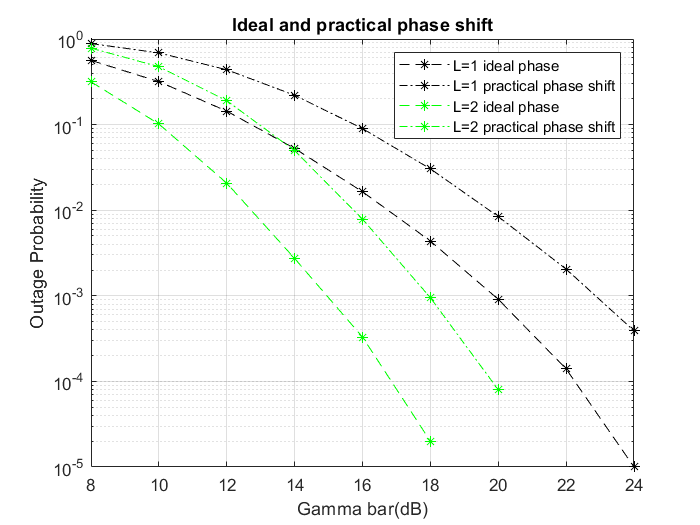

semilogy(Gamma_barldb,prob1,'k--*','MarkerFaceColor','auto');grid on;hold on;
xlabel("Gamma bar(dB)")
ylabel("Outage Probability")


semilogy(Gamma_barldb,prob1phase,'k-.*','MarkerFaceColor','auto');grid on;hold on;



semilogy(Gamma_barldb,prob2,'g--*','MarkerFaceColor','auto');grid on;hold on;


semilogy(Gamma_barldb,prob2phase,'g-.*','MarkerFaceColor','auto');grid on;hold on;


legend("L=1 ideal phase","L=1 practical phase shift", "L=2 ideal phase","L=2 practical phase shift")
title("Ideal and practical phase shift")